# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 06-Oct-2021 18:58:18

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Time", "Vout", "Vin"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable("/home/vlad/Documents/lab3_opamp/10khz.csv", opts);

## Convert to output type

Time = tbl.Time;
Vout = tbl.Vout;
Vin = tbl.Vin;

## Clear temporary variables

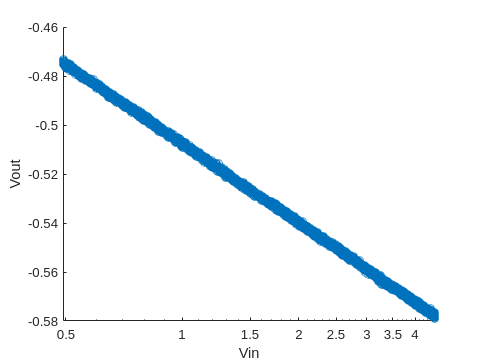

clear opts tbl
scatter(Vin,Vout)
set(gca,'xscale','log')
c = polyfit(Vin,Vout,1);
Vinlog = log(Vin);
xlabel("Vin")
ylabel("Vout")

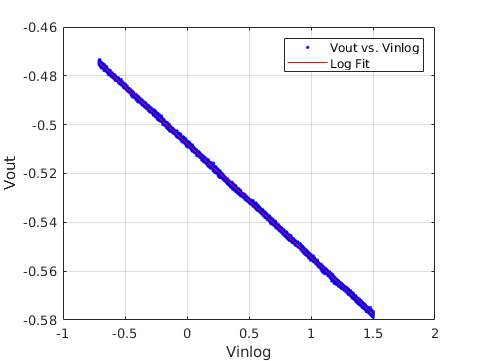

[xData, yData] = prepareCurveData( Vinlog, Vout );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'Log Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Vout vs. Vinlog', 'Log Fit', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Vinlog', 'Interpreter', 'none' );
ylabel( 'Vout', 'Interpreter', 'none' );
grid on

fitresult

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =    -0.04664  (-0.04665, -0.04662)
       p2 =     -0.5077  (-0.5077, -0.5077)

gof

gof = struct with fields:
           sse: 0.0018
       rsquare: 0.9998
           dfe: 8190
    adjrsquare: 0.9998
          rmse: 4.6501e-04


V_t = 25.8e-3

V_t = 0.0258

R = 9700

R = 9700

n = -fitresult.p1 / (V_t)

n = 1.8077

I_s = exp(fitresult.p2/(n * V_t))/R

I_s = 1.9301e-09